- This dataset consists of EEG data from 128 channels. 

- Sampling rate is 250Hz

- Event markers: 

-     Onset of standard stimulus: 1

-     Onset of oddball stimulus: 2

-     Button-press onset of left hand: 256

-     Button-press onset of right hand: 4096

cfg = [];
cfg.dataset = '/Users/sihanliang/Downloads/oddball1_mc_downsampled_eeg.vhdr';

% define trials based on responses
cfg.trialdef.prestim    = 1.5;
cfg.trialdef.poststim   = 2.0;
cfg.trialdef.eventtype  = 'STI102';  % name of trigger channel
cfg.trialdef.eventvalue = [256, 4096];  % 256: button press left;
                                        % 4096: button press right
cfg.trialfun            = 'ft_trialfun_general';
cfg                     = ft_definetrial(cfg);

evaluating trial function 'ft_trialfun_general'
reading the header from '/Users/sihanliang/Downloads/oddball1_mc_downsampled_eeg.vhdr'
reading the events from '/Users/sihanliang/Downloads/oddball1_mc_downsampled_eeg.vhdr'
found 810 events
created 110 trials
the call to "ft_definetrial" took 0 seconds and required the additional allocation of an estimated 7 MB



% preprocess EEG data
cfg.demean              = 'yes';
cfg.dftfilter           = 'yes';
cfg.dftfreq             = [50 100];
cfg.reref               = 'yes';  % re-referencing
cfg.refchannel          = 'all';

data                    = ft_preprocessing(cfg);

processing channel { 'EEG001' 'EEG002' 'EEG003' 'EEG004' 'EEG005' 'EEG006' 'EEG007' 'EEG008' 'EEG009' 'EEG010' 'EEG011' 'EEG012' 'EEG013' 'EEG014' 'EEG015' 'EEG016' 'EEG017' 'EEG018' 'EEG019' 'EEG020' 'EEG021' 'EEG022' 'EEG023' 'EEG024' 'EEG025' 'EEG026' 'EEG027' 'EEG028' 'EEG029' 'EEG030' 'EEG031' 'EEG032' 'EEG033' 'EEG034' 'EEG035' 'EEG036' 'EEG037' 'EEG038' 'EEG039' 'EEG040' 'EEG041' 'EEG042' 'EEG043' 'EEG044' 'EEG045' 'EEG046' 'EEG047' 'EEG048' 'EEG049' 'EEG050' 'EEG051' 'EEG052' 'EEG053' 'EEG054' 'EEG055' 'EEG056' 'EEG057' 'EEG058' 'EEG059' 'EEG060' 'EEG061' 'EEG062' 'EEG063' 'EEG064' 'EEG065' 'EEG066' 'EEG067' 'EEG068' 'EEG069' 'EEG070' 'EEG071' 'EEG072' 'EEG073' 'EEG074' 'EEG075' 'EEG076' 'EEG077' 'EEG078' 'EEG079' 'EEG080' 'EEG081' 'EEG082' 'EEG083' 'EEG084' 'EEG085' 'EEG086' 'EEG087' 'EEG088' 'EEG089' 'EEG090' 'EEG091' 'EEG092' 'EEG093' 'EEG094' 'EEG095' 'EEG096' 'EEG097' 'EEG098' 'EEG099' 'EEG100' 'EEG101' 'EEG102' 'EEG103' 'EEG104' 'EEG105' 'EEG106' 'EEG107' 'EEG108' 'EEG109

在对data_cleaned进行分割后，获得的data_seg_symptom data structure存储了每次OCD episode（也就是每次event）发生时长中采集到的lfp数据。这和本example dataset的结构其实十分类似。本dataset中存储了110个data segment，对应了110个event（button press）。只不过区别在于本dataset中每个data segment对应的时间开始点为event前1.5秒，结束点为event后2秒，也就是说每个data segment的时长是恒定的。而我们的data segment对应的时间范围是从event发生的第0秒开始，一直到event结束。也就是说时间范围是不固定的。

data.time{1}

ans =    -1.5000   -1.4960   -1.4920   -1.4880   -1.4840   -1.4800   -1.4760   -1.4720   -1.4680   -1.4640   -1.4600   -1.4560   -1.4520   -1.4480   -1.4440   -1.4400   -1.4360   -1.4320   -1.4280   -1.4240   -1.4200   -1.4160   -1.4120   -1.4080   -1.4040   -1.4000   -1.3960   -1.3920   -1.3880   -1.3840   -1.3800   -1.3760   -1.3720   -1.3680   -1.3640   -1.3600   -1.3560   -1.3520   -1.3480   -1.3440   -1.3400   -1.3360   -1.3320   -1.3280   -1.3240   -1.3200   -1.3160   -1.3120   -1.3080   -1.3040


data.trial{1}

ans = 	1.0e+-3 *

   -0.0469   -0.0413   -0.0342   -0.0369   -0.0465   -0.0564   -0.0565   -0.0439   -0.0327   -0.0330   -0.0420   -0.0536   -0.0568   -0.0469   -0.0384   -0.0392   -0.0396   -0.0345   -0.0288   -0.0306   -0.0377   -0.0407   -0.0414   -0.0404   -0.0367   -0.0377   -0.0447   -0.0495   -0.0421   -0.0292   -0.0302   -0.0398   -0.0459   -0.0470   -0.0408   -0.0376   -0.0439   -0.0472   -0.0425   -0.0369   -0.0347   -0.0408   -0.0519   -0.0526   -0.0464   -0.0488   -0.0506   -0.0401   -0.0331   -0.0426
   -0.0491   -0.0423   -0.0406   -0.0437   -0.0449   -0.0482   -0.0527   -0.0520   -0.0466   -0.0409   -0.0407   -0.0469   -0.0524   -0.0518   -0.0478   -0.0443   -0.0399   -0.0336   -0.0295   -0.0305   -0.0351   -0.0413   -0.0441   -0.0406   -0.0361   -0.0357   -0.0392   -0.0421   -0.0398   -0.0363   -0.0357   -0.0371   -0.0425   -0.0465   -0.0445   -0.0424   -0.0418   -0.0423   -0.0428   -0.0380   -0.0318   -0.0360   -0.0474   -0.0508   -0.0470   -0.0460   -0.0445   -0.0393 

data.trialinfo

ans =         4096
         256
         256
         256
         256
         256
         256
        4096
        4096
        4096


data_seg_symptom

data_seg_symptom = struct with fields:
         label: {4×1 cell}
       fsample: 415
           cfg: [1×1 struct]
           hdr: [1×1 struct]
         trial: {[4×4566 double]  [4×2491 double]  [4×2076 double]  [4×3736 double]  [4×3736 double]}
          time: {1×5 cell}
    sampleinfo: [5×2 double]


data

data = struct with fields:
           hdr: [1×1 struct]
         label: {128×1 cell}
          time: {1×110 cell}
         trial: {1×110 cell}
       fsample: 250
    sampleinfo: [110×2 double]
     trialinfo: [110×1 double]
           cfg: [1×1 struct]


需要注意的是，本dataset中，两个条件组（left hand vs right hand)所对应的data segment都存储在了这一个data structure中，并通过trial info对其进行区分。而我们则用了两个structure分别存储两个条件组对应的segment。是否需要再将这两个struct进行合并，并手动添加trialinfo field进行标注？* 通过下面的实验证明应该是不需要，分别对两组数据做分析就可以了。*

frequency/spectral analysis

cfg         = [];
cfg.output  = 'pow';
cfg.channel = 'EEG102';
cfg.method  = 'mtmfft';
cfg.taper   = 'hanning';
cfg.foi     = 5:0.5:40;

cfg.trials   = find(data.trialinfo(:,1) == 256);
spectr_left  = ft_freqanalysis(cfg, data)

the input is raw data with 128 channels and 110 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 55/55 nfft: 875 samples, datalength: 875 samples, 1 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB


spectr_left = struct with fields:
        label: {'EEG102'}
       dimord: 'chan_freq'
         freq: [5.1429 5.4286 6 6.5714 7.1429 7.4286 8 8.5714 9.1429 9.4286 10 10.5714 11.1429 11.4286 12 12.5714 13.1429 13.4286 14 14.5714 15.1429 15.4286 16 16.5714 17.1429 17.4286 18 18.5714 19.1429 19.4286 20 20.5714 21.1429 21.4286 22 22.5714 … ]
    powspctrm: [2.2515e-12 1.8567e-12 1.3494e-12 1.3163e-12 9.8106e-13 8.0866e-13 6.6034e-13 6.7200e-13 7.7827e-13 7.0339e-13 7.3182e-13 7.1820e-13 5.3812e-13 5.4876e-13 6.7181e-13 5.7282e-13 4.6886e-13 4.3860e-13 4.3269e-13 5.1731e-13 7.0738e-13 … ]
          cfg: [1×1 struct]



cfg.trials   = find(data.trialinfo(:,1) == 4096);
spectr_right = ft_freqanalysis(cfg, data)

the input is raw data with 128 channels and 110 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 55/55 nfft: 875 samples, datalength: 875 samples, 1 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB


spectr_right = struct with fields:
        label: {'EEG102'}
       dimord: 'chan_freq'
         freq: [5.1429 5.4286 6 6.5714 7.1429 7.4286 8 8.5714 9.1429 9.4286 10 10.5714 11.1429 11.4286 12 12.5714 13.1429 13.4286 14 14.5714 15.1429 15.4286 16 16.5714 17.1429 17.4286 18 18.5714 19.1429 19.4286 20 20.5714 21.1429 21.4286 22 22.5714 … ]
    powspctrm: [1.7423e-12 1.6558e-12 1.0580e-12 8.8077e-13 7.5811e-13 6.9120e-13 5.9335e-13 5.6827e-13 5.1190e-13 4.4449e-13 7.5366e-13 5.3588e-13 6.4275e-13 5.7664e-13 5.8888e-13 5.4095e-13 5.2711e-13 4.3290e-13 4.6334e-13 5.7405e-13 4.8452e-13 … ]
          cfg: [1×1 struct]


figure
hold on;
plot(spectr_left.freq, (spectr_left.powspctrm), 'linewidth', 2)
plot(spectr_left.freq, (spectr_right.powspctrm), 'linewidth', 2)%left and right same length
legend('Button press left', 'Button press right')
xlabel('Frequency (Hz)')
ylabel('Power (\mu V^2)')

Time-frequency analysis

cfg            = [];
cfg.output     = 'pow';
cfg.channel    = 'all';
cfg.method     = 'mtmconvol';
cfg.taper      = 'hanning';
cfg.toi        = -1 : 0.10 : 1.5;
cfg.foi        = 2:2:40;
cfg.t_ftimwin  = ones(size(cfg.foi)) * 0.5;

cfg.trials     = find(data.trialinfo(:,1) == 256);
tfr_left       = ft_freqanalysis(cfg, data);

the input is raw data with 128 channels and 110 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 55, frequency 20 (40.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 73 MB



cfg.trials     = find(data.trialinfo(:,1) == 4096);
tfr_right      = ft_freqanalysis(cfg, data);

the input is raw data with 128 channels and 110 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
trial 55, frequency 20 (40.00 Hz), 1 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 51 MB


absolute baseline

cfg              = [];
cfg.baseline     = [-0.5 -0.1];
cfg.baselinetype = 'absolute';
cfg.xlim         = [0.4 0.8];  % specified in seconds
cfg.ylim         = [16 24];    % we only plot the beta band
cfg.zlim         = 'maxabs';
cfg.marker       = 'on';
cfg.colorbar     = 'yes';
cfg.layout       = 'natmeg_customized_eeg1005.lay';

figure;
ft_topoplotTFR(cfg, tfr_left);
title('Left hand reaction');


reading layout from file natmeg_customized_eeg1005.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 4 MB
the input is freq data with 128 channels, 20 frequencybins and 26 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_topoplotTFR" took 2 seconds and required the additional allocation of an estimated 33 MB


figure;

ft_topoplotTFR(cfg, tfr_right);
title('Right hand reaction');

relative baseline

cfg              = [];

reading layout from file natmeg_customized_eeg1005.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 128 channels, 20 frequencybins and 26 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 0 seconds and required the additional allocation of an estimated 0 MB


cfg.baseline     = [-0.5 -0.1];

cfg.baselinetype = 'relative';  % we use a relative baseline
cfg.xlim         = [0.4 0.8];
cfg.ylim         = [16 24];
cfg.zlim         = 'maxabs';
cfg.marker       = 'on';
cfg.colorbar     = 'yes';
cfg.layout       = 'natmeg_customized_eeg1005.lay';

figure;
ft_topoplotTFR(cfg, tfr_left);
title('Left hand reaction');

figure;
ft_topoplotTFR(cfg, tfr_right);
title('Right hand reaction');

TFR

cfg          = [];

reading layout from file natmeg_customized_eeg1005.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 128 channels, 20 frequencybins and 26 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 0 seconds and required the additional allocation of an estimated 1 MB


cfg.colorbar = 'yes';

cfg.zlim     = 'maxabs';
cfg.ylim     = [10 Inf];  % plot alpha band upwards
cfg.layout   = 'natmeg_customized_eeg1005.lay';

reading layout from file natmeg_customized_eeg1005.lay
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is freq data with 128 channels, 20 frequencybins and 26 timebins
the call to "ft_freqbaseline" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_topoplotTFR" took 0 seconds and required the additional allocation of an estimated 1 MB


cfg.channel  = 'EEG126';

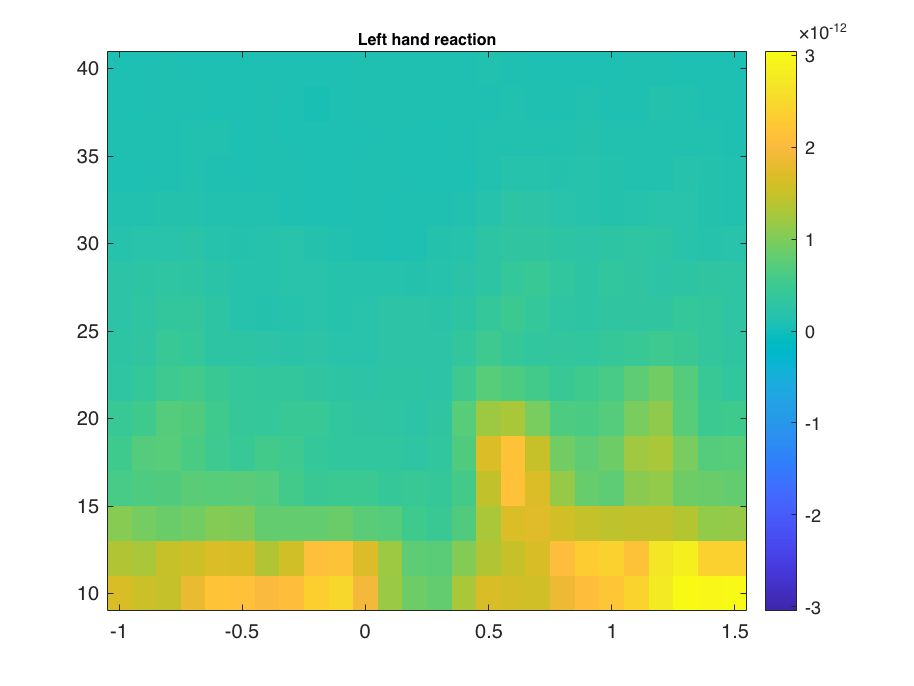

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_singleplotTFR" took 1 seconds and required the additional allocation of an estimated 6 MB



figure;
ft_singleplotTFR(cfg, tfr_left);
title('Left hand reaction');
